## Frequency Modulation

% Clear workspace and close figures
clear all;
close all;

% Load the audio file
audioFile = 'videoplayback.wav';
[x, fs] = audioread(audioFile);

% Play the original audio
sound(x, fs); % Play the audio using the sound function
disp('Playing audio...'); % Add a message to the console

Playing audio...


pause(length(x) / fs); % Pause to allow time for audio playback
disp('Audio playback completed.'); % Display a completion message

Audio playback completed.


% Split audio into left and right channels
l = x(:, 1); % Left audio
r = x(:, 2); % Right audio

t = (0:length(x) - 1) / fs;

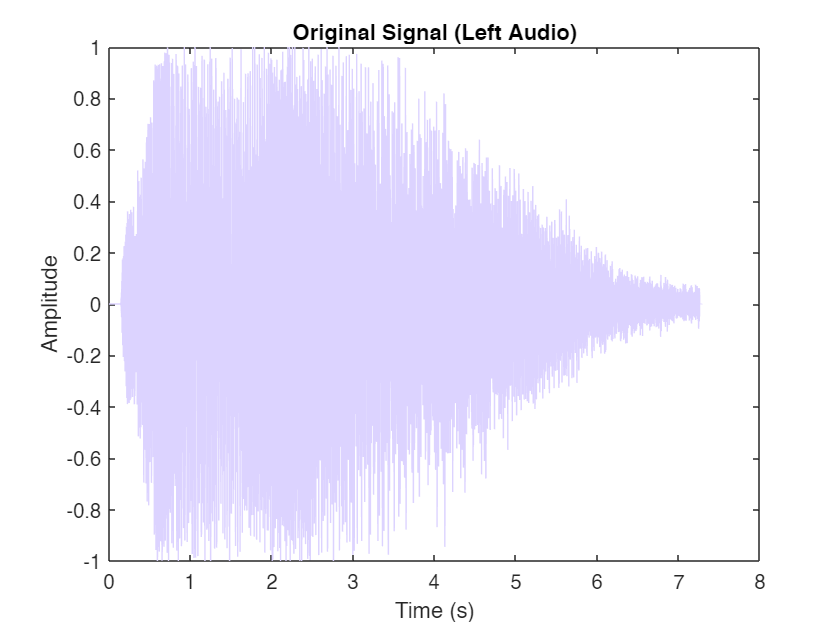

% Plot the original signal in the time domain (Left Audio)
figure;
plot(t, l, 'Color', '#dcd3ff');
title('Original Signal (Left Audio)');
xlabel('Time (s)');
ylabel('Amplitude');

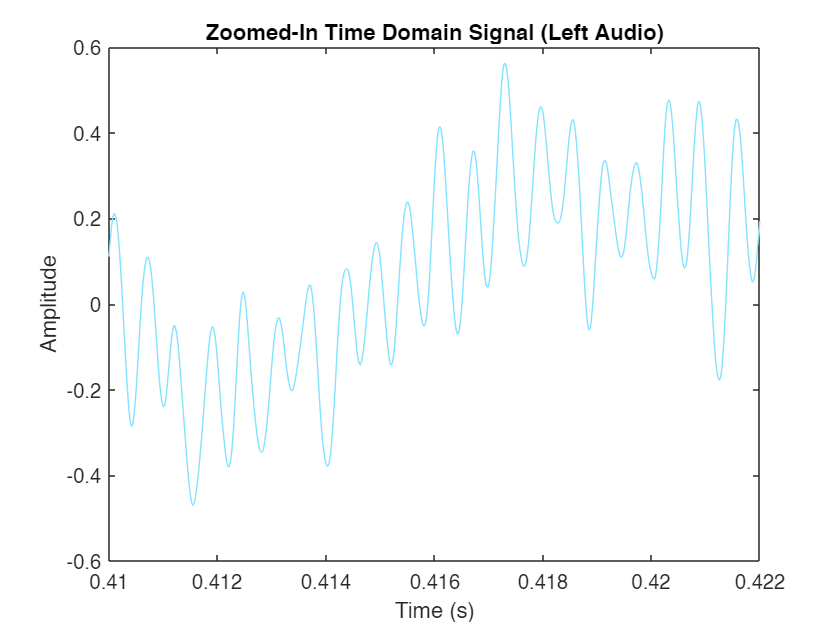


% Zoom in on a specific part of the time domain signal (Left Audio)
zoomStartTime = 0.41; % Start time for zoom (in seconds)
zoomEndTime = 0.422; % End time for zoom (in seconds)
zoomIdx = (t >= zoomStartTime) & (t <= zoomEndTime);

figure;
plot(t(zoomIdx), l(zoomIdx), 'Color', '#85e3ff');
title('Zoomed-In Time Domain Signal (Left Audio)');
xlabel('Time (s)');
ylabel('Amplitude');

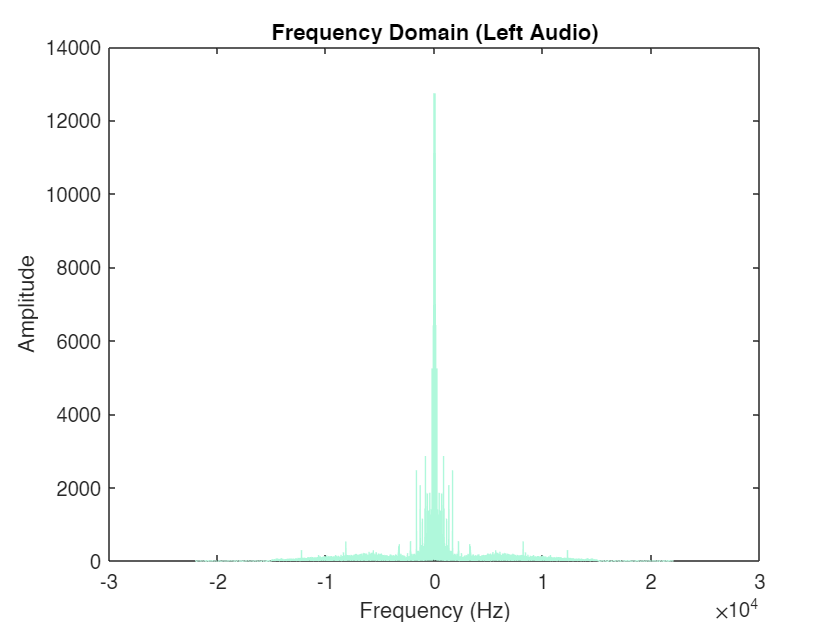


% Plot the original signal in the frequency domain (Left Audio)
L = fft(l);
f = (-length(L)/2:length(L)/2 - 1) * fs / length(L);

figure;
plot(f, abs(fftshift(L)), 'Color', '#aff8db');
title('Frequency Domain (Left Audio)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

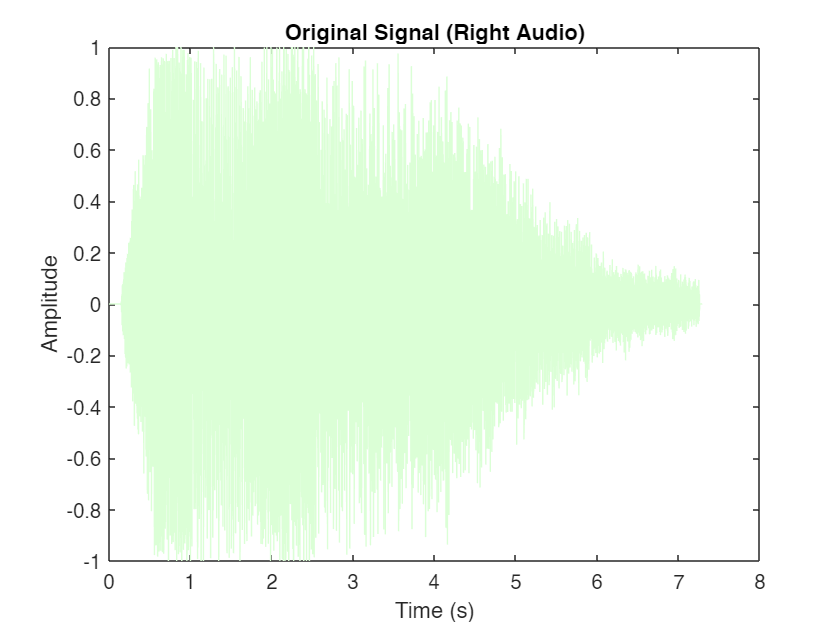

% Plot the original signal in the time domain (Right Audio)
figure;
plot(t, r, 'Color', '#dbffd6');
title('Original Signal (Right Audio)');
xlabel('Time (s)');
ylabel('Amplitude');

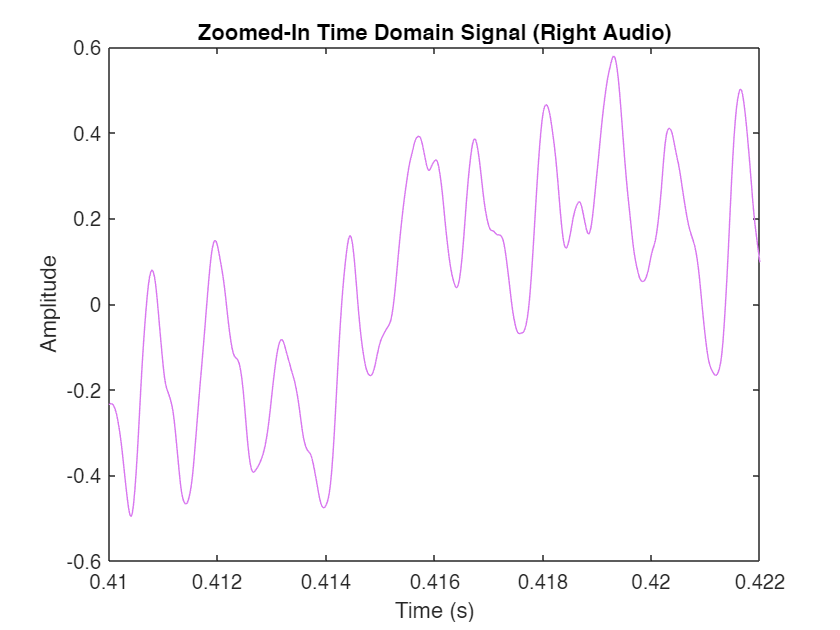


% Zoom in on a specific part of the time domain signal (Right Audio)
zoomStartTime = 0.41; % Start time for zoom (in seconds)
zoomEndTime = 0.422; % End time for zoom (in seconds)
zoomIdx = (t >= zoomStartTime) & (t <= zoomEndTime);

figure;
plot(t(zoomIdx), r(zoomIdx), 'Color', '#d877ef');
title('Zoomed-In Time Domain Signal (Right Audio)');
xlabel('Time (s)');
ylabel('Amplitude');

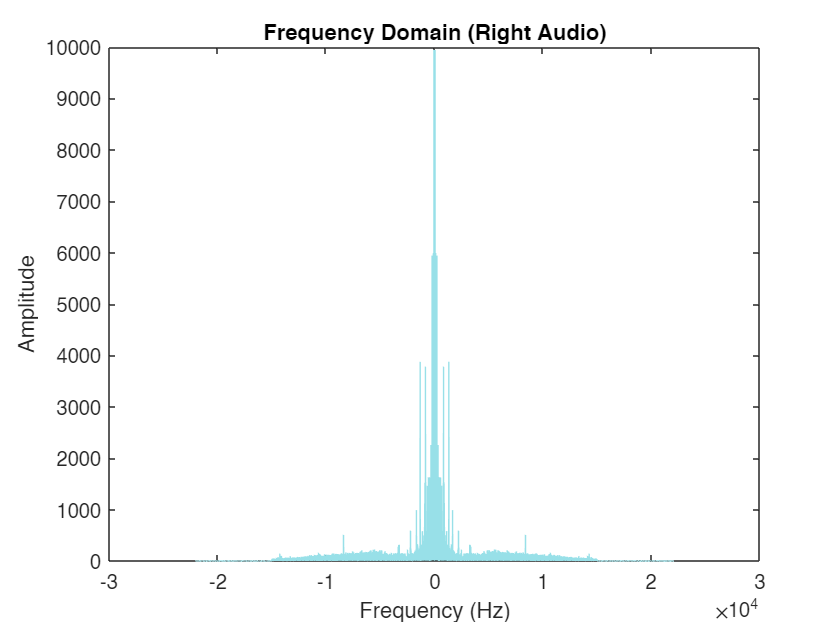


% Plot the original signal in the frequency domain (Right Audio)
R = fft(r);
f = (-length(R)/2:length(R)/2 - 1) * fs / length(R);

figure;
plot(f, abs(fftshift(R)), 'Color', '#98e0e8');
title('Frequency Domain (Right Audio)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

% Calculate the carrier frequency (fc)
fc = 1e6;

% Generate the carrier wave and reshape it to match the audio signal
wc = 2 * pi * fc * t;
wc = reshape(wc, size(l));

% Parameters for zooming in on a plot
zoomStartTime = 0.41; % Start time for zoom (in seconds)
zoomEndTime = 0.411; % End time for zoom (in seconds)
zoomIdx = (t >= zoomStartTime) & (t <= zoomEndTime);

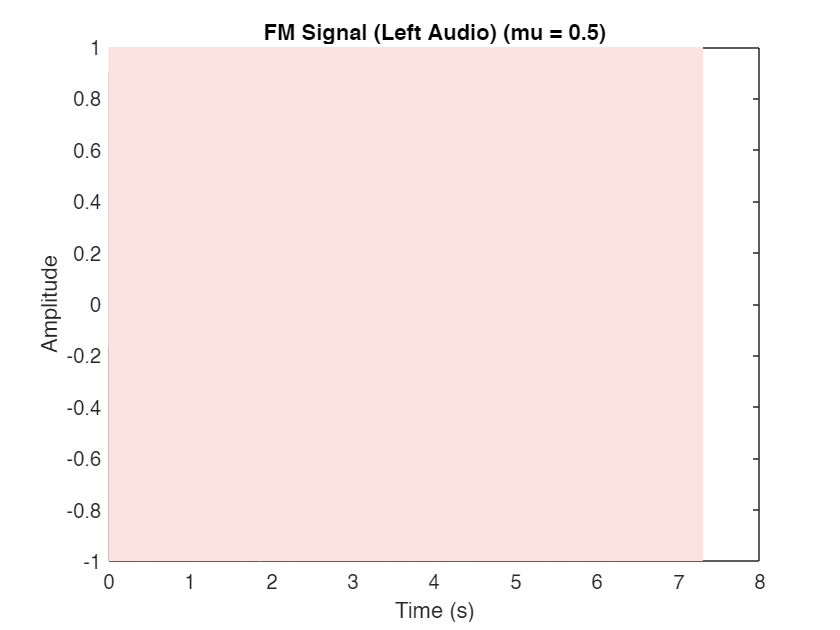

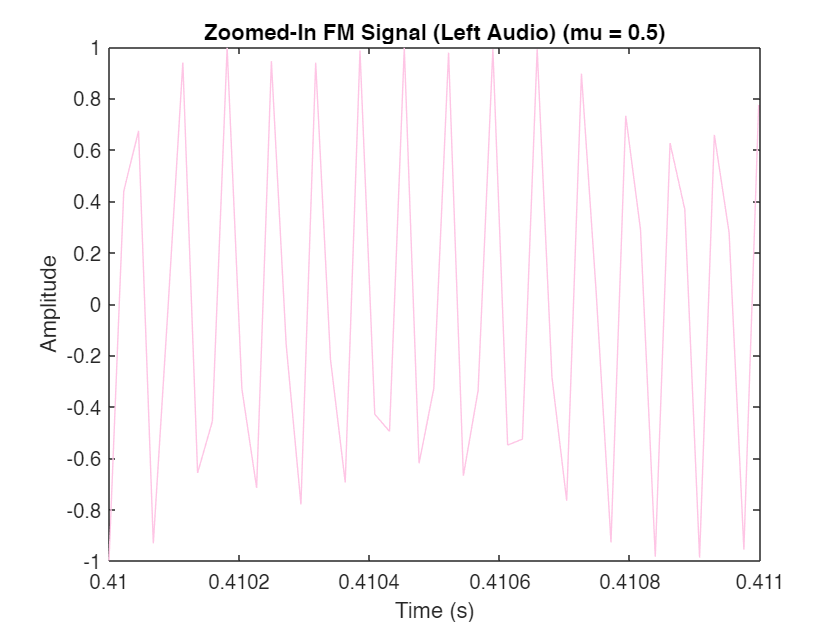

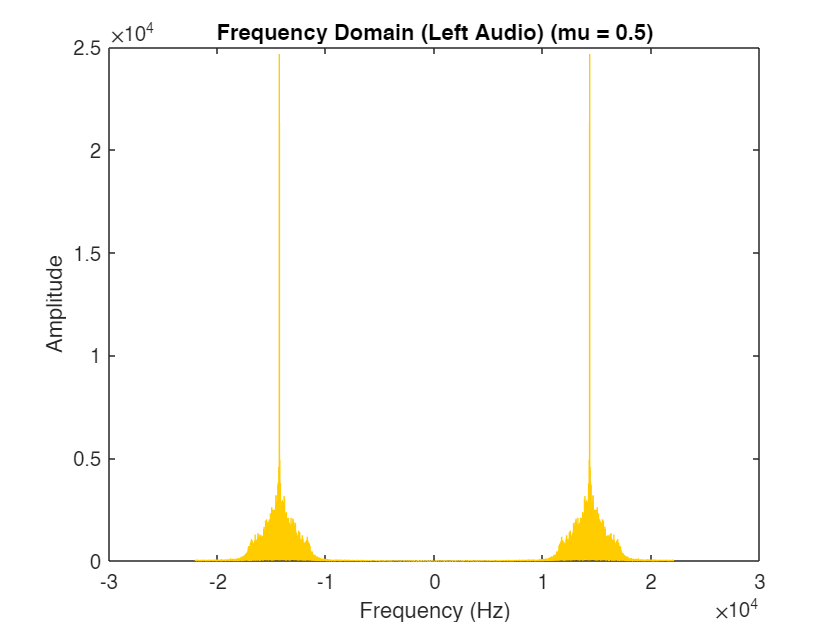

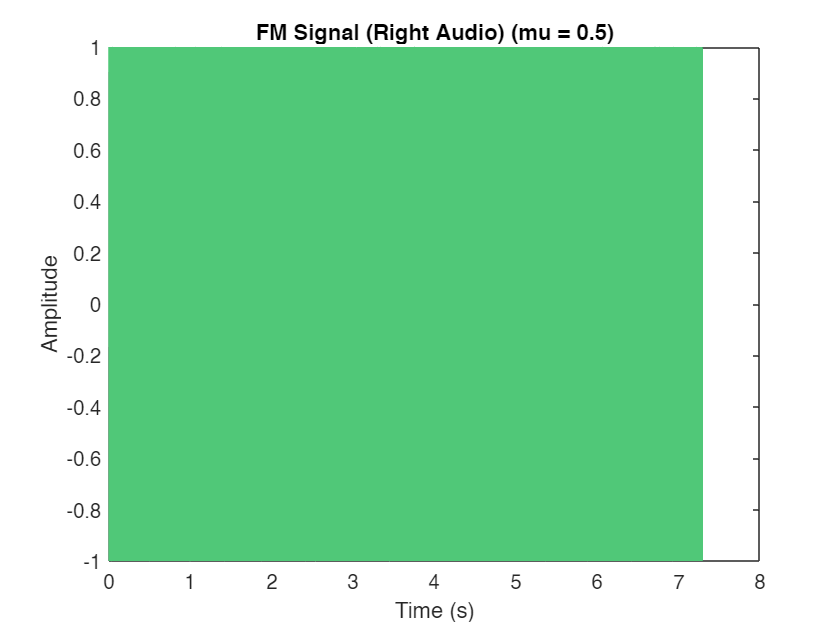

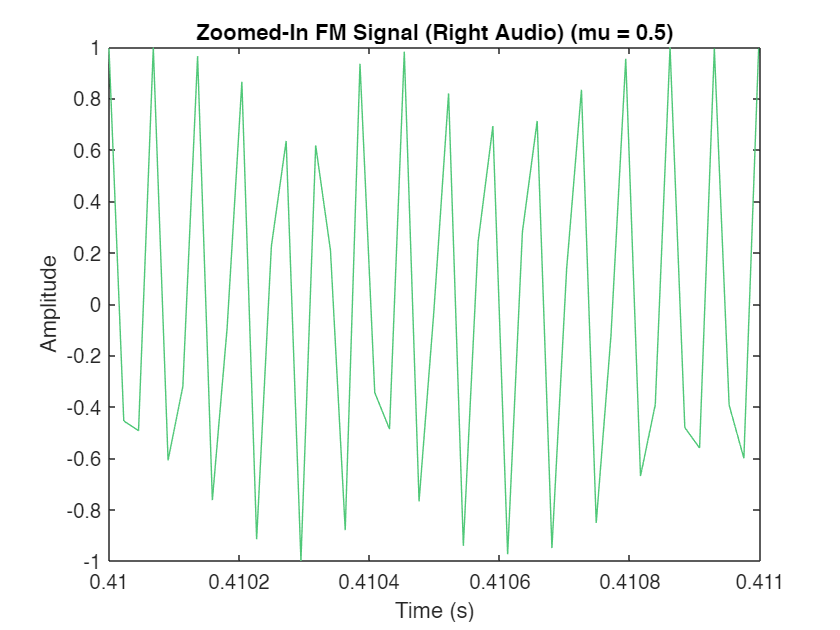

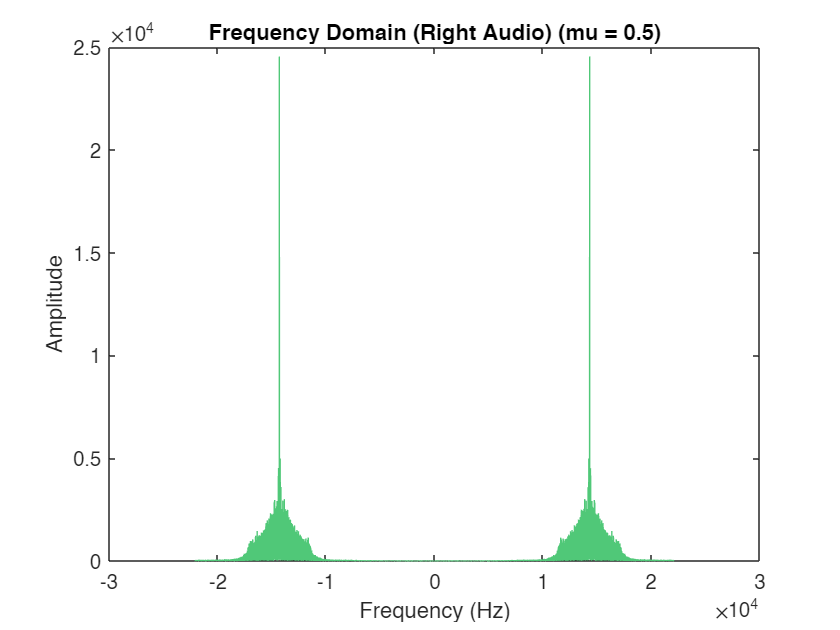

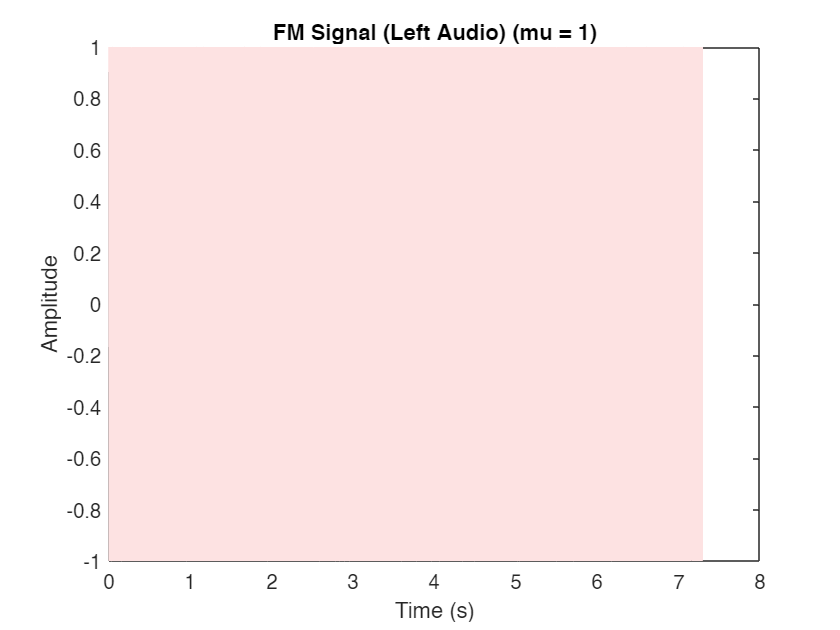

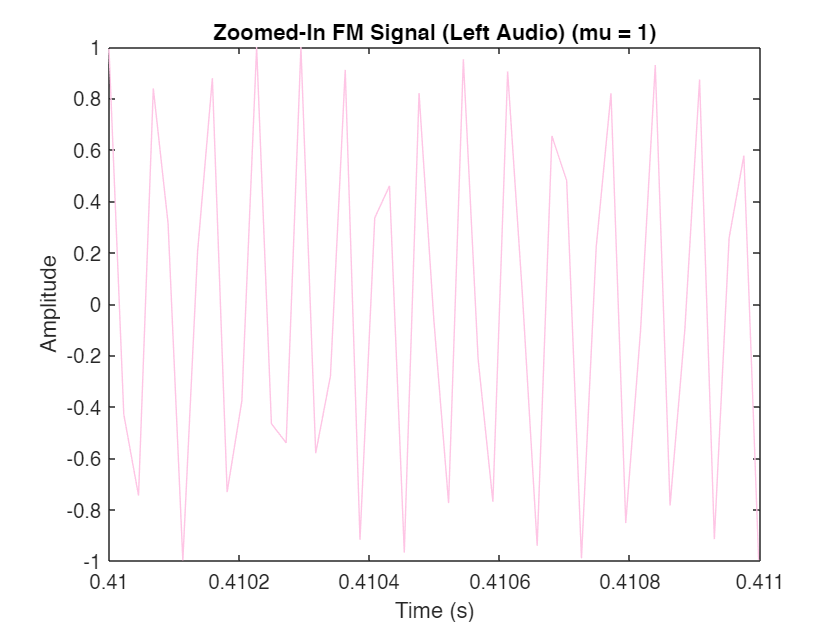

mu = [0.5 1 2]; % Modulation Indices

for i = 1:length(mu)
    % Modulate the left audio signal
    y = cos(wc + mu(i) * cumsum(l));
    
    % Plot the modulated signal in the time domain
    figure;
    plot(t, y, 'Color', '#fde2e2');
    title(['FM Signal (Left Audio) (mu = ' num2str(mu(i)) ')']);
    xlabel('Time (s)');
    ylabel('Amplitude');
    
    % Plot the zoomed-in signal
    figure;
    plot(t(zoomIdx), y(zoomIdx), 'Color', '#fec5e5');
    title(['Zoomed-In FM Signal (Left Audio) (mu = ' num2str(mu(i)) ')']);
    xlabel('Time (s)');
    ylabel('Amplitude');
    
    % Plot the modulated signal in the frequency domain
    Y = fft(y);
    f = (-length(Y)/2:length(Y)/2 - 1) * fs / length(Y);
    
    figure;
    plot(f, abs(fftshift(Y)), 'Color', '#ffcc00');
    title(['Frequency Domain (Left Audio) (mu = ' num2str(mu(i)) ')']);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    
    % Modulate the right audio signal
    y = cos(wc + mu(i) * cumsum(r));
    
    % Plot the modulated signal in the time domain
    figure;
    plot(t, y, 'Color', '#50C878');
    title(['FM Signal (Right Audio) (mu = ' num2str(mu(i)) ')']);
    xlabel('Time (s)');
    ylabel('Amplitude');
    
    % Plot the zoomed-in signal
    figure;
    plot(t(zoomIdx), y(zoomIdx), 'Color', '#50C878');
    title(['Zoomed-In FM Signal (Right Audio) (mu = ' num2str(mu(i)) ')']);
    xlabel('Time (s)');
    ylabel('Amplitude');
    
    % Plot the modulated signal in the frequency domain
    Y = fft(y);
    f = (-length(Y)/2:length(Y)/2 - 1) * fs / length(Y);
    
    figure;
    plot(f, abs(fftshift(Y)), 'Color', '#50C878');
    title(['Frequency Domain (Right Audio) (mu = ' num2str(mu(i)) ')']);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
end